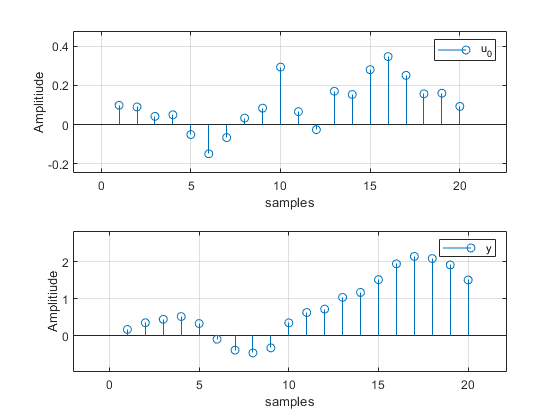

clc; clear; close all;
%% Input Generation
N = 20;
u0 = 0;
v_1 = randn(1);

for i=1:N
v = 0.1*randn(1);
u0 = 0.5*u0+v+0.5*v_1;
U0(i) = u0;
v_1 = v;
end
subplot(211);
stem(U0);
xlabel('samples');
ylabel('Amplitiude');
legend('u_0');
grid on;
%% https://medium.com/auquan/time-series-analysis-for-finance-arma-models-21695e14c999
%% Output Generation
y_1 = 0;
y_2 = 0;
u_1 = 0;
u_2 = 0;

for i = 1:N
  y = 1.5*y_1-0.7*y_2+2*U0(i)-u_1+0.5*u_2;
  y_2 = y_1;
  y_1 = y;
  u_2 = u_1;
  u_1 = U0(i);
  Y(i) = y+v;
end
subplot(212);
stem(Y);
xlabel('samples');
ylabel('Amplitiude');
legend('y');
grid on;

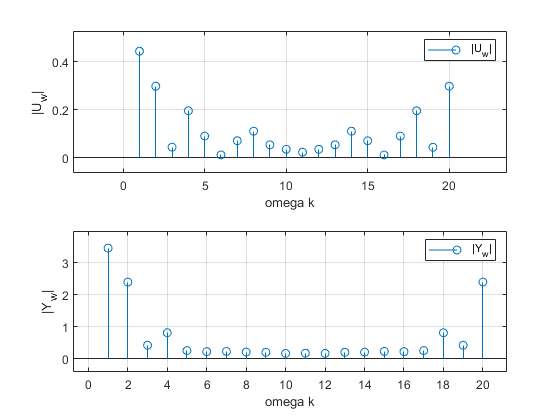


% %% FFT Calculation
for k = 0:N-1
 wk = 2*pi*k/N;
 Uw(k+1) = 0;
 Yw(k+1) = 0;
 
 for t = 1:N-1
   Uw(k+1) = U0(t+1)*exp(-1i*wk*t)+Uw(k+1);
   Yw(k+1) = Y(t+1)*exp(-1i*wk*t)+Yw(k+1);   
 end
Uw(k+1) = 1/sqrt(N)*Uw(k+1);
Yw(k+1) = 1/sqrt(N)*Yw(k+1);    
end
figure
subplot(211);
stem(abs(Uw));
xlabel('omega k')
ylabel('|U_w|');
grid on;
legend('|U_w|');
subplot(212);
stem(abs(Yw));
xlabel('omega k')
ylabel('|Y_w|');
grid on;
legend('|Y_w|');

% %%
t0 = 1;
t1 = 1;
syms teta1 teta2 teta3 teta4 teta5 
for k = 0:N-1
 Phi_k = exp(-1i*2*pi*k/N);
 Ak(k+1) = 1+teta1*Phi_k+teta2*Phi_k^2;
 Bk(k+1) = teta3+teta4*Phi_k+teta5*Phi_k^2;
 Gk(k+1) = Bk(k+1)/Ak(k+1);
 Ik(k+1) = t0+t1*Phi_k;
 Tk(k+1) = Ik(k+1)/Ak(k+1);
end

% subplot(211);
% stem(Ak);
% xlabel('samples');
% ylabel('Amplitiude');
% legend('y');

% subplot(211);
% stem(AK);
% xlabel('samples');
% ylabel('Amplitiude');
% legend('y');
% grid on;

%% 
m = 1;
for k = 0:N-1
for j = N-1:-1:0
K(k+1,m) = 1/Ak(k+1)*exp(-(2*pi*k/N)*j);     
end
m = m+1;
end

Va = 0;
Vb = 0;
Vc = 0;
Vd = 0;
rho = 0.1;
% 
g =0;
for i = 1:N
Va = Va+(norm(Yw(i)-Gk(i)))^2/((norm(Gk(i)))^2+rho);
Vb = Vb+conj((Yw(i)-Gk(i)))/((norm(Gk(i)))^2+rho)*K(i,:);
Vc = Vc+1/((norm(Gk(i)))^2+rho)*(conj(K(i,:)))'*K(i,:);
Vd = Vd+(conj(K(i,:)))'*((Yw(i)-Gk(i)))/((norm(Gk(i)))^2+rho);
g = g+log10((norm(Gk(i)))^2+rho);
end
f = abs(log10((1/N*(Va-Vb*Vc^-1*Vd))))+g/N;

clc;
clear;
close all;
load('x0');
options = optimset('PlotFcns',@optimplotfval);
[x,fval,exitflag,output] = fminsearch(@mobjectivefcn,x,options);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 15.859488 



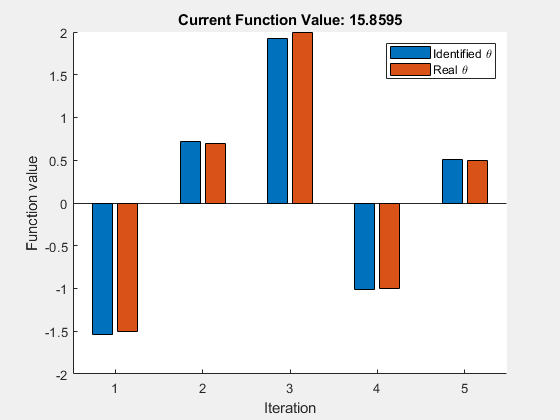

teta_real = [-1.5 0.7 2 -1 0.5];
bar([x;teta_real]');
legend('Identified \theta','Real \theta');